# Homework 10 (Solutions)

Math 3607, Autumn 2021

Tae Eun Kim

clear, close all, format short 

## Problem 1 (Interpolating population; FNC 5.1.2)

(a,b)

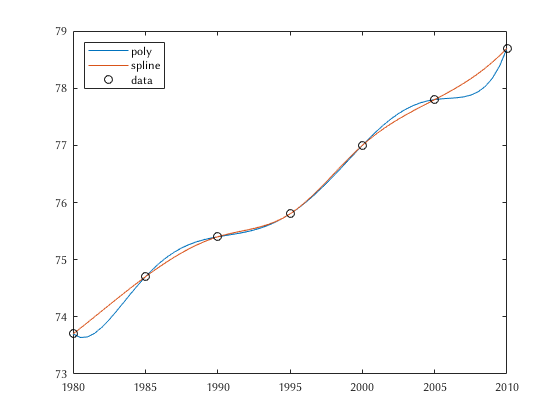

tdp = [1980:5:2010] - 1980;                    % abscissas: year since 1980
ydp = [73.7 74.7 75.4 75.8 77.0 77.8 78.7];    % ordinates: expectancy
n = length(tdp);
t = linspace(1980, 2010, 61)-1980;             % all half-years since 1980
ypoly = polyval(polyfit(tdp,ydp,n-1), t);
yspl = interp1(tdp, ydp, t, 'spline');
clf
plot(t+1980, ypoly), hold on
plot(t+1980, yspl)
plot(tdp+1980, ydp, 'ko')
legend('poly', 'spline', 'data', 'Location', "Northwest")

(c) By how `t` was constructed, the 6th from the last element correspond to year 2007.

1980+t(end-6)

ans = 2007

So the estimate expectancy for a person born in 2007 was already computed and stored:

ypoly(end-6)

ans = 77.8475

yspl(end-6)

ans = 78.0842

Based on the graph abvoe, the result by spline (78.084) appears to be more believeable. 

**Note.** You can find a single estimate directly by using `polyfit` or `interp1` as well:

targetYear = 2007;
polyval(polyfit(tdp,ydp,n-1), targetYear-1980)

ans = 77.8475

interp1(tdp, ydp, targetYear-1980, "spline")

ans = 78.0842

## Problem 2 (Piecewise cubic interpolation; FNC 5.1.3)

One may directly type in the given coordinates. In real applications, such information may be stored in data files, *e.g.,*

and

If these files are saved in the same directory as your main live script, you can import the data using `load` function

load('shape_top.dat')
load('shape_bottom.dat')

The data files are now loaded and  are stored as `shape_top` and `shape_bottom:`

shape_top

shape_top =          0         0
    0.5100    0.1600
    0.9600    0.1600
    1.0600    0.4300
    1.2900    0.6200
    1.5500    0.4800
    1.7300    0.1900
    2.1300    0.1800
    2.6100         0


shape_bottom

shape_bottom =          0         0
    0.5800   -0.1600
    1.0400   -0.1500
    1.2500   -0.3000
    1.5600   -0.2900
    1.7600   -0.1200
    2.1900   -0.1200
    2.6100         0


### Version 1.

With the data-loading tip out of the way, let's go ahead and plot the saucer. 

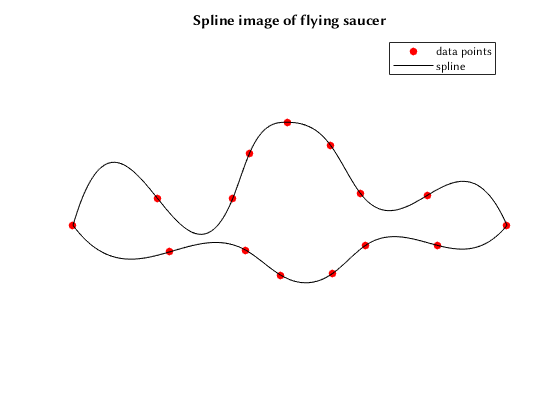

% top
xdp_t = shape_top(:,1);
ydp_t = shape_top(:,2);
x_t = linspace(xdp_t(1), xdp_t(end), 200)';
y_t = interp1(xdp_t, ydp_t, x_t, 'spline');

% bottom
xdp_b = shape_bottom(:,1);
ydp_b = shape_bottom(:,2);
x_b = linspace(xdp_b(1), xdp_b(end), 200)';
y_b = interp1(xdp_b, ydp_b, x_b, 'spline');

% plot
clf
plot([xdp_t; xdp_b], [ydp_t; ydp_b], 'r.', 'MarkerSize', 20), hold on
plot([x_t; flip(x_b)], [y_t; flip(y_b)], 'k')
axis equal, axis off
title('Spline image of flying saucer')
legend('data points', 'spline')

### Version 2.

A cleaner version using a for-loop a new type of MATLAB array called *cells*:

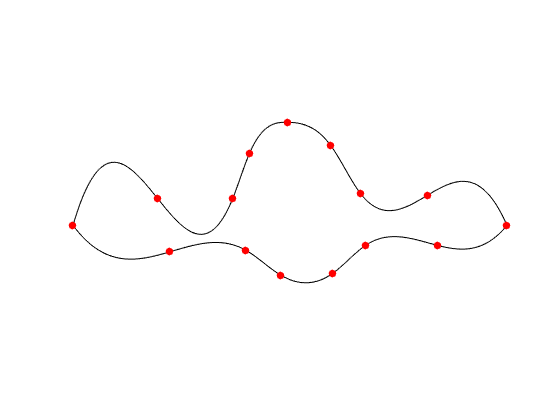

DATA{1} = shape_top;         % DATA is a cell array.
DATA{2} = shape_bottom;
clf
for i = 1:2
    xdp = DATA{i}(:,1);
    ydp = DATA{i}(:,2);
    x = linspace(xdp(1), xdp(end), 200)';
    y = interp1(xdp, ydp, x, 'spline');
    plot(x, y, 'k'), hold on
    plot(xdp, ydp, 'r.', 'MarkerSize', 20)
    hold on
end
axis equal, axis off

If you learn more about cell arrays and structures, read **LM** Section 6.3.

## Problem 3 (Quadratic interpolant by hand; FNC 5.1.4)

Note that the function $q(x)$ is a quadratic polynomial:

$q(x) = \frac{a}{2} x(x-1) - b(x-1)(x+1) + \frac{c}{2} x (x+1)$.

(a) Confirming that $q$ is an interpolant of the three given points is to check the following:

- $q(-1) = \frac{a}{2} (-1)(-2) - b(-2)(0) + \frac{c}{2} (-1) (0) = a$.

- $q(0)  = \frac{a}{2} (0)(-1) - b(-1)(1) + \frac{c}{2} (0)(1) = b$.

- $q(1)  = \frac{a}{2} (1)(0) - b(0)(2) + \frac{c}{2} (1) (2) = c$.

(b) Let $\phi(t) = \frac{t-x_0}{h}$.  Then

- $\phi( x_0 ) = 0$,

- $\phi(x_0 \pm h) = \pm 1$.

This provides a suitable change of variables: define $p$ by


$$p(t) = q(\phi(t)) = \frac{a}{2} \frac{t-x_0}{h} \frac{ t - x_0 - h}{h} - b \frac{t-x_0-h}{h} \frac{t-x_0+h}{h} + \frac{c}{2} \frac{t-x_0}{h} \frac{t-x_0+h}{h}$$


which simplifies to

$p(t) = \frac{1}{h^2} \left[ \frac{a}{2} (t-x_0) (t-x_0-h) - b (t-x_0 -h) (t-x_0 +h) + \frac{c}{2} (t-x_0)(t-x_0+h) \right]$.

This is clearly a quadratic polynomial (as a composition of linear and quadratic polynomial). Furthermore, it interpolates all three points $(x_0-h, a)$, $(x_0,b)$, and $(x_0+h,c)$ by construction. For instance,

$p(x_0-h) = q(\phi(x_0-h)) = q(-1) = a$,

where the first equality follows from the definition $p(t) = q(\phi(t))$, the second due to the noted property of the map $\phi(t)$, and the last from the fact that $q$ interpolates $(-1, a)$. 

## Problem 4 (Cardinal cubic splines; FNC 5.3.5)

A slight modification of in-class demo would do. For the sake of comparison, cardinal piecewise linear interpolants, a.k.a. hat functions, are also plotted.

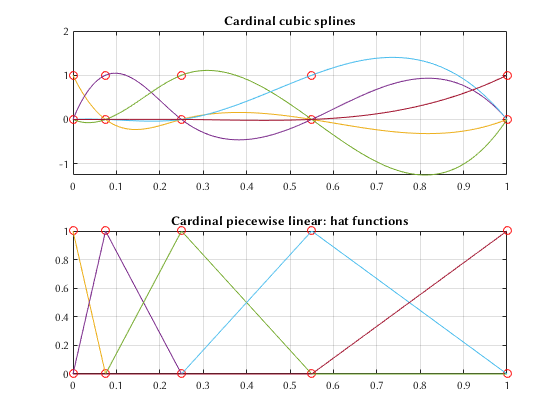

xdp = [0 0.075 0.25 0.55 1]';  % t is the nodes (x data points)
I = eye(length(xdp));          % identity matrix for easy access to cardinal data (y)
x = linspace(0, 1, 400)';
clf
subplot(2,1,1)
plot(xdp, zeros(size(xdp)), 'ro'), hold on
plot(xdp, ones(size(xdp)), 'ro')
for j = 1:length(xdp)
    plot(x, interp1(xdp, I(:,j), x, 'spline'))
end
grid on
title('Cardinal cubic splines')

subplot(2,1,2)
plot(xdp, zeros(size(xdp)), 'ro'), hold on
plot(xdp, ones(size(xdp)), 'ro')
for j = 1:length(xdp)
    plot(x, interp1(xdp, I(:,j), x))
end
grid on
title('Cardinal piecewise linear: hat functions')

## Problem 5 (Piecewise quadratic spline; adapted from FNC 5.3.6)

Denote by $Q(x)$ the quadratic spline that interpolates $(x_i, y_i)$, for $i = 1, \ldots, n$, such that

$Q(x) = q_i(x) = c_{i,1} + c_{i,2}(x-x_i) + c_{i,3}(x-x_i)^2$ on $I_i$ for $i = 1, \ldots, n-1$

where $I_i = [x_i, x_{i+1})$, for $i = 1, \ldots, n-2$, and $I_{n-1} = [x_{n-1}, x_n]$. So there are $3(n-1) = 3n-3$ coefficients to be determined. 

The function $Q$ must interpolate the given data:

$Q(x_i) = y_i$ for $i = 1, \ldots, n$                     [ $n$ equations ]

Since $Q$ must be $C^1[x_1, x_n]$, $Q$ and $Q'$ must be continuous at all interior breakpoints, that is, the function values and the first derivatives must match at all interior knots:

$q_{i-1}(x_i) = q_i(x_i)$ for $i = 2,\ldots, n-1$         [ $n-2$ equations ]

$q\prime_{i-1}(x_i) = q\prime_i(x_i)$ for $i = 2, \ldots, n-1$         [ $n-2$ equations ]

All together, there are $3n -4$ equations, that is, one condition short of the $3n-3$ conditions required. (Just in the case of cubic splines, there are various ways to fill in this missing condition, *e.g.*, by setting $Q'(x_1) = 0$ or $Q\prime\prime(x_0) = 0$.

## Problem 6 (Cubic splines in 2-D; LM 12.2--15)

(a) Without loss of any generality, we will work with the unit circle $x^2 + y^2 = 1$, which can be parametrized by the arclength variable $s$ as

$\langle x(s), y(s) \rangle = \langle \cos(s), \sin(s) \rangle$, $s \in [0, 2\pi]$. 

(Note that the parametrization by $s$ is equivalent to the usual parametrization by $\theta$ because along the unit circle the length of the arc spanned by angle $\theta$ is equals $\theta$.)

Thus we view $x$ and $y$ as separate variables dependent on a common variable $s$, which we take as the pseudo-arclength. Modifying the script `an_ant.m` in the textbook:

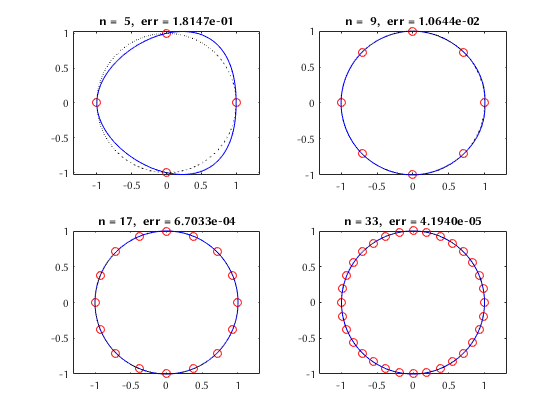

nvals = [5 9 17 33];               % n values to be used
nq = 1001;                         % # of query points (used for plotting)
clf
for j = 1:length(nvals)
    n = nvals(j);
    tdp = linspace(0, 2*pi, n)';    % abscissas
    xdp = cos(tdp);                 % x-ordinates
    ydp = sin(tdp);                 % y-ordinates
    dsdp = sqrt(diff(xdp).^2 + diff(ydp).^2);
    sdp = [0; cumsum(dsdp)];        % pseudo-arclength
    
    s = linspace(sdp(1), sdp(n), nq);    % query points
    x = spline(sdp, xdp, s);             % same as "ppx=spline(sdp,xdp); x=ppval(ppx,s);"
    y = spline(sdp, ydp, s);             % same as "ppy=spline(sdp,ydp); y=ppval(ppy,s);"
    
    ss = 2*pi*s/s(end);                  % scaled query points on [0, 2*pi]; see note below
    xcirc = cos(ss);                     % x-coord. on the circle (for comparison)
    ycirc = sin(ss);                     % y-coord. on the circle (for comparison)
    err = max( sqrt((x-xcirc).^2 + (y-ycirc).^2) );
    
    subplot(2,2,j)
    plot(xdp, ydp, 'ro'), hold on   % plot data points
    plot(x, y, 'b')                 % plot spline
    plot(xcirc, ycirc, 'k:')        % plot circle
    axis equal
    title(sprintf('n = %2d,  err = %10.4e', n, err))
end

Note that the query points $s_j$, for $j = 1,\ldots, 1001$, are scaled to be on $[0, 2\pi]$ by


$$\tilde{s}_j = 2\pi \frac{s_j}{s_{1001}}$$


in obtaining the points on the circle corresponding to the points on the spline curve. That is, 

$\displaystyle \underbrace{ (x_j, y_j) = (p_x(s_j), p_y(s_j)) }_{\text{spline}} \;\longleftrightarrow \quad \underbrace{(\tilde{x}_j, \tilde{y}_j) = (\cos(\tilde{s}_j), \sin(\tilde{s}_j))}_{\text{circle}}$.

This ensures that any pair of corresponding points are on the same ray eminating from the origin, with the angle being $\tilde{s}_j$.

(a,i) Now to specify the first derivatve values at the end points (this is called the *clamped cubic spline*), prepend and append the values to the vector of ordinates, in our case, `xdp `and `ydp`. MATLAB's `spline` is programmed, when it recognizes that the second input has exactly two more elements than the first input, to use the interior elements as data points while the first and the last elements as derivative values at the end points. In this problem, since $x'(s) = -\sin(s)$ and $y'(s) = \cos(s)$, we need to encode $\displaystyle x'(0) = x'(2\pi) = 0$ and $y'(0) = y'(2\pi) = 1$ appropriately by, e.g., 

See below for more details. 

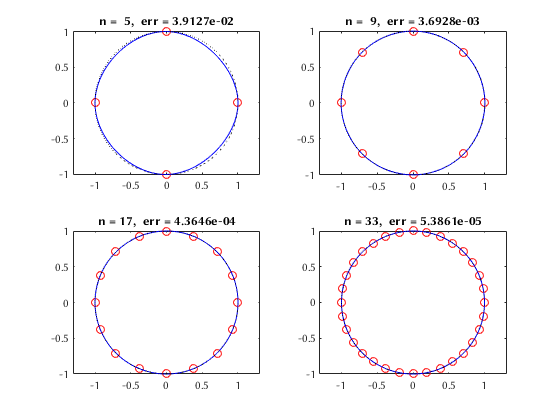

clf
for j = 1:length(nvals)
    n = nvals(j);
    tdp = linspace(0, 2*pi, n)';    % abscissas
    xdp = cos(tdp);                 % x-ordinates
    ydp = sin(tdp);                 % y-ordinates
    dsdp = sqrt(diff(xdp).^2 + diff(ydp).^2);
    sdp = [0; cumsum(dsdp)];        % pseudo-arclength
    
    s = linspace(sdp(1), sdp(n), nq);    % query points
    x = spline(sdp, [0; xdp; 0], s);     % x-coord. clamped spline
    y = spline(sdp, [1; ydp; 1], s);     % y-coord. clamped spline
    
    ss = 2*pi*s/s(end);                  % scaled query points on [0, 2*pi]
    xcirc = cos(ss);                     % x-coord. on the circle (for comparison)
    ycirc = sin(ss);                     % y-coord. on the circle (for comparison)
    err = max( sqrt((x-xcirc).^2 + (y-ycirc).^2) );
        
    subplot(2,2,j)
    plot(xdp, ydp, 'ro'), hold on   % plot data points
    plot(x, y, 'b')                 % plot spline
    plot(xcirc, ycirc, 'k:')        % plot circle
    axis equal
    title(sprintf('n = %2d,  err = %10.4e', n, err))
end

(b) We only provide solutions for clamped spline here. The ellipse is parametrized by

$x =  \cos(t)$ and $y = 3\sin(t)$, for $t \in [0, 2\pi]$,

and it is suggested that we use the parameter $t$ in locating points to calculate the error. So the strategy is as follows:

- Let $n$ be the number of query points. Choose a sufficiently large number, e.g., `nq = 1001`.

- Grab $n$ evenly spaced points $t_j$, for $j=1, \ldots, n$, on $[0, 2\pi]$.

- Grab $n$ points on the ellipsed $(x_j, y_j) = (\cos(t_j), 3\sin(t_j))$.

- Calculate the distances between two adjacent points $\Delta s_k = \sqrt{(x_{k+1}-x_k)^2 + (y_{k+1}-y_k)^2}$, for $k = 1, \ldots, n-1$.

- Define $s_j =  \sum_{k=1}^{j-1} \Delta s_k$, for $j = 1, \ldots, n$. In particular, note that $s_1 = 0$. 

- Rescale $s_j$ by $s_j \to \mathtt{sdp(end)} \cdot \frac{s_j}{s_n}$, for $j = 1, \ldots, n$.

See below for the implementation of the strategy.

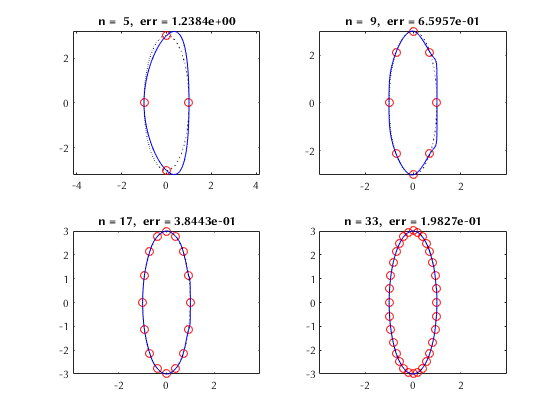

clf
for j = 1:length(nvals)
    n = nvals(j);
    tdp = linspace(0, 2*pi, n)';    % abscissas
    xdp = cos(tdp);                 % x-ordinates
    ydp = 3*sin(tdp);               % y-ordinates
    dsdp = sqrt(diff(xdp).^2 + diff(ydp).^2);
    sdp = [0; cumsum(dsdp)];        % pseudo-arclength
    
    t = linspace(0, 2*pi, nq)';          % query points t on [0, 2*pi] as suggested in problem
    xell = cos(t);                       % x-coord. on the ellipse (for comparison)
    yell = 3*sin(t);                     % y-coord. on the ellipse (for comparison)
    
    dsell = sqrt(diff(xell).^2 + diff(yell).^2);
    sell = [0; cumsum(dsell)];           % pseudo-arclength corresponding to t-query points
    s = sdp(end)*sell/sell(end);         % rescaled pseudo-arclength
    x = spline(sdp, [0; xdp; 0], s);     % x-coord. clamped spline
    y = spline(sdp, [3; ydp; 3], s);     % y-coord. clamped spline
    err = max( sqrt((x-xell).^2 + (y-yell).^2) );
        
    subplot(2,2,j)
    plot(xdp, ydp, 'ro'), hold on   % plot data points
    plot(x, y, 'b')                 % plot spline
    plot(xell, yell, 'k:')          % plot ellipse
    axis equal
    title(sprintf('n = %2d,  err = %10.4e', n, err))
end

### Using arclength instead of pseudo-arclength

For those of you who may wonder how the same problems can be solved using the arclength parameter instead of pseudo-arclength parameter, see below.

(a) 

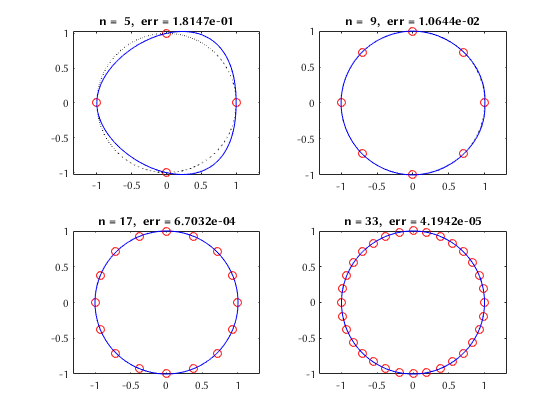

nvals = [5 9 17 33];
clf
for j = 1:length(nvals)
    n = nvals(j);
    sdp = linspace(0, 2*pi, n)';    % nodes: arc length
    xdp = cos(sdp);                 % ordinates: x-coord.
    ydp = sin(sdp);                 % ordinates: y-coord.
    
    s = linspace(0, 2*pi, 1000)';   % query points
    xcirc = cos(s);                 % x-coord. on circle
    ycirc = sin(s);                 % y-coord. on circle
    x = interp1(sdp, xdp, s, 'spline');
    y = interp1(sdp, ydp, s, 'spline');
    
    err = max( sqrt((x-xcirc).^2 + (y-ycirc).^2) );
    
    subplot(2,2,j)
    plot(xdp, ydp, 'ro'), hold on   % plot data points
    plot(xcirc, ycirc, 'k:')        % plot circle
    plot(x, y, 'b')                 % plot spline
    axis equal
    title(sprintf('n = %2d,  err = %10.4e', n, err))
end

(a,i) 

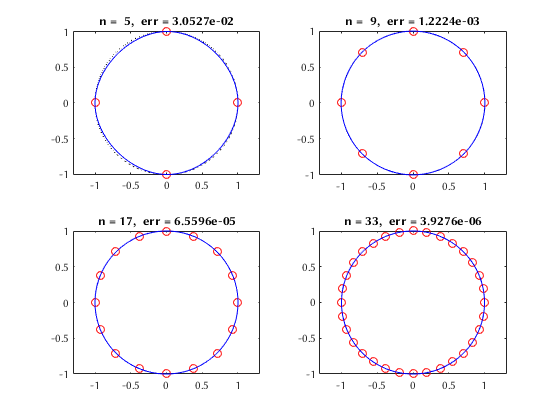

clf
for j = 1:length(nvals)
    n = nvals(j);
    sdp = linspace(0, 2*pi, n)';    % nodes: arc length
    xdp = [0; cos(sdp); 0];         % ordinates: x-coord.
    ydp = [1; sin(sdp); 1];         % ordinates: y-coord.
    
    s = linspace(0, 2*pi, 1000)';   % query points
    xcirc = cos(s);                 % x-coord. on circle
    ycirc = sin(s);                 % y-coord. on circle
    x = spline(sdp, xdp, s);
    y = spline(sdp, ydp, s);
    
    err = max( sqrt((x-xcirc).^2 + (y-ycirc).^2) );
    
    subplot(2,2,j)
    plot(xdp(2:end-1), ydp(2:end-1), 'ro'), hold on   % plot data points
    plot(xcirc, ycirc, 'k:')        % plot circle
    plot(x, y, 'b')                 % plot spline
    axis equal
    title(sprintf('n = %2d,  err = %10.4e', n, err))
end

(b)  

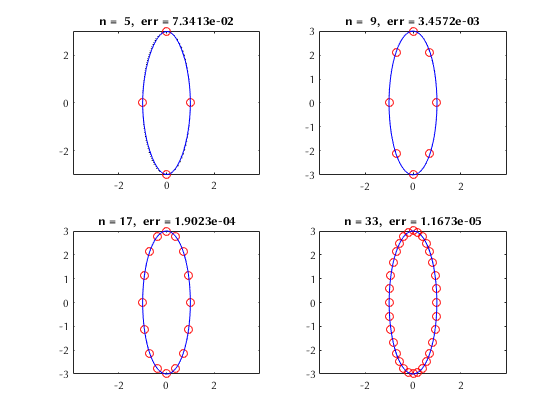

clf
for j = 1:length(nvals)
    n = nvals(j);
    tdp = linspace(0, 2*pi, n)';    % nodes: arc length
    xdp = [0; cos(tdp); 0];         % ordinates: x-coord.
    ydp = [3; 3*sin(tdp); 3];       % ordinates: y-coord.
    
    t = linspace(0, 2*pi, 1000)';   % query points
    xell = cos(t);                  % x-coord. on ellipse
    yell = 3*sin(t);                % y-coord. on ellipse
    x = spline(tdp, xdp, t);
    y = spline(tdp, ydp, t);
    
    err = max( sqrt((x-xell).^2 + (y-yell).^2) );
    
    subplot(2,2,j)
    plot(xdp(2:end-1), ydp(2:end-1), 'ro'), hold on   % plot data points
    plot(xell, yell, 'k:')          % plot ellipse
    plot(x, y, 'b')                 % plot spline
    axis equal
    title(sprintf('n = %2d,  err = %10.4e', n, err))
end

As you may have noticed, this approach involves less manipulation, especially when it comes to calculating errors (no rescaling needed), and appears to be more accurate than the former approach. 